# Receive IQ Samples with ADALM-PLUTO

This script receives IQ samples of BPSK  message from the transmitter Pluto.

#### Receiver configuration

First, we need to specify the parameters to set up the SDR for receiving a signal:

- ***fc***: Carrier frequency at 868 MHz.

- ***fs***: Sampling frequency, ensuring synchronization with the transmitter.

- ***rxGain***: Gain of the receiver. 0 dB is used here.

- ***samplesPerSymbol***: Defines how many samples represent a single symbol (matches the transmitter).

% Receiver settings
 fc = 868e6;         % Carrier frequency
 fs = 1e6;           % Sampling frequency (matching transmitter's fs)
 rxGain = 0;        % Receiver gain 
 samplesPerSymbol = 8; % Must match transmitter's samplesPerSymbol  

#### **Opening a session on PLUTO SDR**

For opening the session we need to sepecify the RF Settings. We create a receiver object (***rx***) for the ADALM-PLUTO SDR, with the following parameters:

- **"RadioID":** Identifies the connected SDR.

- **"BasebandSampleRate":** Matches the sampling frequency **fs**.

- **"SamplesPerFrame":** Specifies how many samples are captured in each frame (8192 samples in this case).

- **"CenterFrequency":** Tunes the SDR to the carrier frequency **fc**.

- **"Gain":** Sets the receive gain to control signal amplification.

rx = sdrrx(...
    "Pluto", ...
    "RadioID", "usb:0", ...
    "BasebandSampleRate", fs, ...
    "SamplesPerFrame", 8192, ...
    "CenterFrequency", fc, ...
    "Gain", rxGain);

rx.OutputDataType       = 'double';

**Receiving on PLUTO SDR**

Now we acquire a block of IQ samples. 

While the transmitter (first Pluto) is sending the data, we need  to receive with the second pluto, uncommenting the first line that performs the operation "*capture(rx,rx.SamplesPerFrame)*"  to receive live samples from the SDR

However, in this case, for analyzing the obtained resutls from the previous transmission, we can load the pre-captured samples (***rxSamples***) from the provided file ***Rx_samples_def.mat*** for testing or debugging purposes.

%rxSamples = capture(rx,rx.SamplesPerFrame);
rxSamples=load("Rx_samples_def.mat").rxSamples;

#### Capturing the data

% % Capture samples
disp('Receiving data...');

#### Representing the received signal

Now, the real (in blue) and imaginary (in red) parts of the received IQ samples are plotted to inspect the raw data.

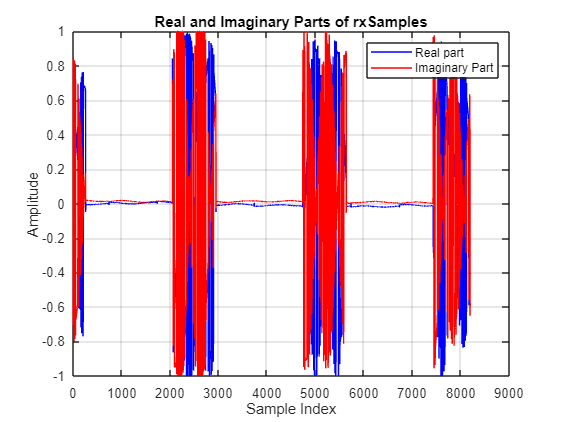

% Plotting real and imaginary parts of rxSamples
figure()

plot(real(rxSamples), 'b');
hold on;
plot(imag(rxSamples), 'r');

title('Real and Imaginary Parts of rxSamples');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real part','Imaginary Part')
grid on;

As we can see in the previous graph, we are receiving the data in bursts. In the previous example we can see 3 complete bursts and at the beginning of the graph the final part of the first burst. This is coherent since with the first pluto and the first program (*BPSK_Transmitte.mlx*) we are seding the IQ samples with zeros at the beggining and at the end continuously. Basically, this is what we are seeing in each burst, some zeros, the signal, and the final zeros. Clearly these zeros are making it easier to differentiate between the different bursts of data.

#### Selecting only 1 burst

Now, although the receiver Pluto has captured 4 bursts, we just want one of them for analyzing it. Therefore, a specific burst of the received signal (***burst1***) is extracted from indices 1500 to 3500. Basically, this isolates a single BPSK frame for processing. In fact, if we represent the extracted burst in a graph, we can see how we are getting some zeros, the BPSK signal, and some more zeros. 

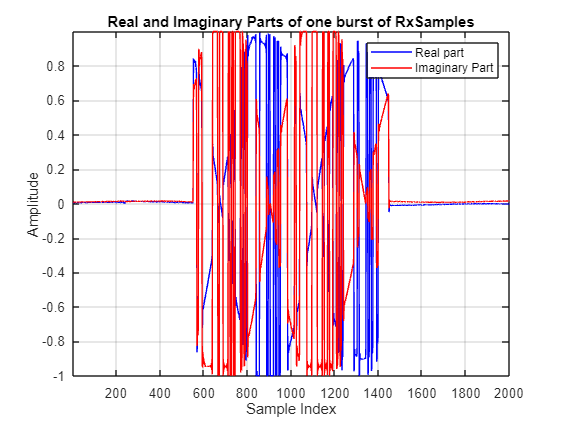

% Extracting the burst of samples
burst1 = rxSamples(1500:3500);

% Plotting real and imaginary parts of 1 burst of rxSamples
figure()

plot(real(burst1), 'b');
hold on;
plot(imag(burst1), 'r');

title('Real and Imaginary Parts of one burst of RxSamples');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real part','Imaginary Part')
axis tight
grid on;

#### Representing the constellation and spectrum

We already have the received signal saved in the variable "***burst1***". In the previous section we have represented it in time. But we can also represent it's constellation. The constellation diagram shows the distribution of symbols in the IQ plane.

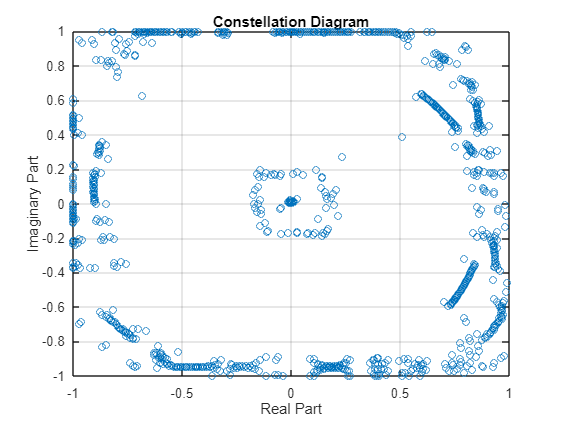

% Create a figure
figure();

%Constellation diagram
plot(real(burst1), imag(burst1), 'o', 'MarkerSize', 5, 'DisplayName', 'Constellation Points');
grid on;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Constellation Diagram');

Analyzing the previous constellation, that represents the **raw, uncorrected IQ samples** received by the SDR, we can see how it doesn't look like a BPSK constellation at all. In fact, in the diagram appears  a **circle with some samples scattered near the origin**. This strange constellation appears because of the lack of syncronization between the transmitter and receiver SDRs, due to 2 factors: 

- **Frequency Offset: **A mismatch between the carrier frequencies of the transmitter and receiver causes the constellation points to rotate over time, leading to the circular pattern.

- **Phase Offset: **Any initial phase misalignment between the transmitter and receiver further distorts the alignment of the constellation points, preventing them from clustering properly.

These combined effects indicate that the transmitter and receiver are not yet synchronized in terms of frequency and phase, which is why the constellation does not yet resemble a proper BPSK diagram.

However, to ensure that the received signal is correct before applying frequency and phase corrections, we examine its spectrum using the next cell of code:

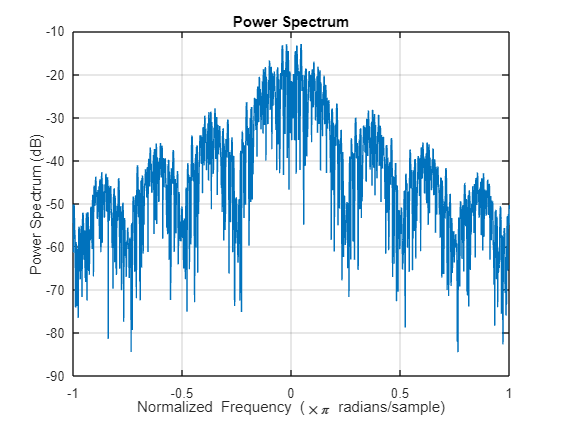

%Power spectrum
figure()
pspectrum(burst1);
title('Power Spectrum');
grid on;

From the previous spectrum, we can get some insights. 

We know that  for a BPSK signal, the spectrum should resemble a **sinc-like shape**, which is characteristic of rectangular pulse shaping. This shape is caused by the sharp transitions in the BPSK modulated signal. In fact, looking at the previous graph, the spectrum has the shape that we were expecting. 

With the representation of the spectrum, we verify that the received signal matches the expected spectral characteristics of a BPSK transmission, which confirms that the receiver is capturing the transmitted signal correctly, even though the constellation diagram shows imperfections due to synchronization issues.

Therefore, the spectrum is a reliable indicator of signal correctness, regardless of synchronization issues in the constellation. Once we confirm that the spectrum matches the expected BPSK sinc shape, we can proceed with frequency and phase correction to fix the constellation, that we are going to do in the next code cell.

#### **Frequency and phase correction**

After the previous insights, we can correct the the frequency and phase offset trying to get the proper BPSK constellation. In order to achieve this, we can use the two slide bars called: 

- **Frequency Offset (*****freqOffset*****)** compensates for mismatches between the transmitter and receiver frequencies.

- **Phase Offset (*****phi*****)** adjusts for phase errors.

Trying different values for these offsets, the signal can be corrected. Therefore, we can move them looking at the constellation representation below, until we get the desired BPSK constellation.

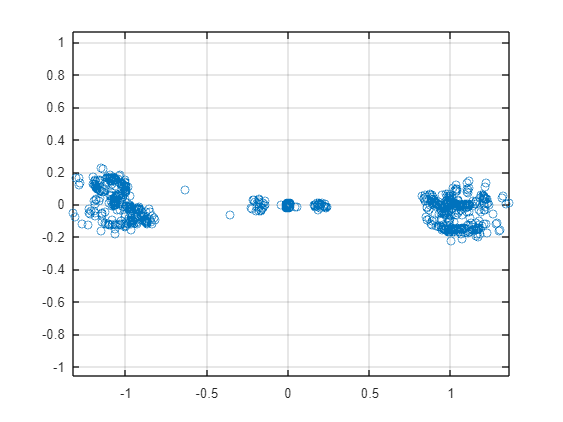

% Freq and phase correction
freqOffset = -1098;
phi = -8;

phaseOffset = exp(1i*deg2rad(phi));

N = numel(burst1);
Ts = 1/(fs);
t = (0:N-1)'.*Ts;
freqOffsetSignal = exp(1i*2*pi*freqOffset.*t);

shiftedSignal = burst1.*freqOffsetSignal;
shiftedSignal = shiftedSignal.*phaseOffset;

figure ()

plot(real(shiftedSignal), imag(shiftedSignal), 'o')
grid on
axis('equal');

After some trials, we get that the optimal values for the frequency and phase offset are -1098 Hz and -8 degrees respectively.  In fact, after applying these offsets, the constellation diagram becomes properly aligned to the expected BPSK pattern, with two distinct clusters along the real axis (In-Phase axis), representing the two possible BPSK symbols (+1 and -1). 

However, even after applying these offsets, some **noise** in the received signal results in residual points appearing near the center of the constellation diagram. These are outliers caused by imperfections in the received signal, such as:

- Thermal noise

- Multi-path effects

- Imperfect synchronization

These central points do not represent valid BPSK symbols and will be **removed later** during the signal processing steps, such as:

- **Energy Detection:** To separate the meaningful signal from noise.

- **Symbol Synchronization:** To align symbols and isolate valid samples.

#### Visualization of the corrected signal

Now, the corrected signal is plotted in the IQ plane to verify proper alignment of the BPSK constellation points.

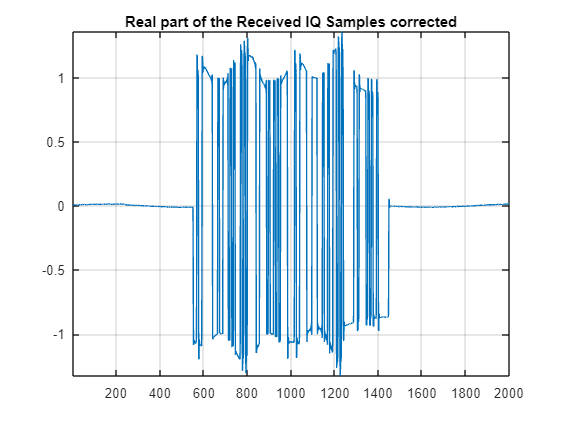

rx_corrected=shiftedSignal;

% Plot the corrected signal

figure()
plot (real(rx_corrected)) 
grid on
axis tight
title("Real part of the Received IQ Samples corrected")

Clearly, with this time representation, we can see how most of the received symbols take a value around +1 and -1, which is what we were expecting after the frequency and phase synchronization.

#### Energy detection

Now, we need to identify the valid and invalid symbols, since we had added in previous sections some zeros at the beginning and at the end of each burst. Therefore, we need to remove these zeros from the chosen burst. For doing this, we need to apply energy detection, calculating the magnitude or absolute value of the corrected signal. 

We start by representing this magnitude in the following graph.

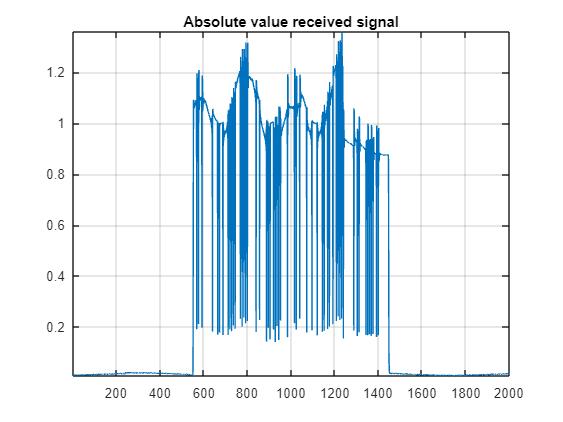

mag = abs(rx_corrected); 

% Plot detected signal
figure
plot (mag)
grid on
axis tight
title("Absolute value received signal")

Analyzing the graph, we can clearly see how the information or data symbols are mostly over 0.2. Therefore, we can discriminate the information symbols from the noise using a threshold around 0.1. This is what we are going to do in the following section.

#### Threshold to remove noise

Here, the signal's magnitude (***mag***) is thresholded to separate noise from valid symbols. Thanks to the previous graph, we choose as a threshold 0.1. This means that we are only going to keep the received values that are over this threshold, because the rest is going to be considered noise. 

Our final signal will be "***pulse***", where only samples above the threshold are kept as part of the clean signal.

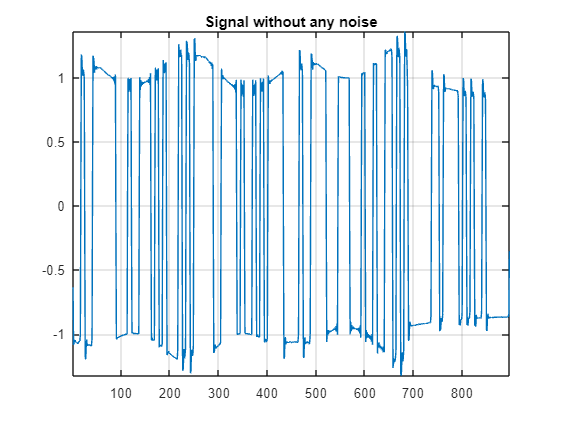

% Threshold to separate signal from noise
threshold   = 0.1;                % Static threshold (it varies depending on the captured signal)
indices     = mag >= threshold;   % Find indices where the signal is above the threshold
pulse       = rx_corrected(indices); % Keep only significant values

% Plot
figure
plot (real(pulse))
grid on
axis tight
title("Signal without any noise")

From the previous representation, we can see how we don't have zeros any more, now we only have the information signal, and, since its a BPSK signal, all the levels are around +1 and -1.

#### Symbol synchronization

After applying a **threshold to remove noise**, we separate the meaningful signal from the background noise by keeping only the significant values (i.e., values above the threshold). However, even after this step, the **symbols may not be aligned properly** due to the lack of synchronization between the transmitter and receiver. Therefore, we need to do some symbol synchronization, to ensure that:

- The receiver identifies the **correct starting point** for each symbol.

- The samples corresponding to each symbol are properly grouped, leading to accurate decoding.

To achieve this, we need to do 2 different steps:

- **Energy Calculation:** The energy of the signal is calculated at various offsets within a symbol's duration.

- **Optimal Offset Selection:** The offset with the **maximum energy** is selected, as this aligns the receiver with the transmitted symbols.

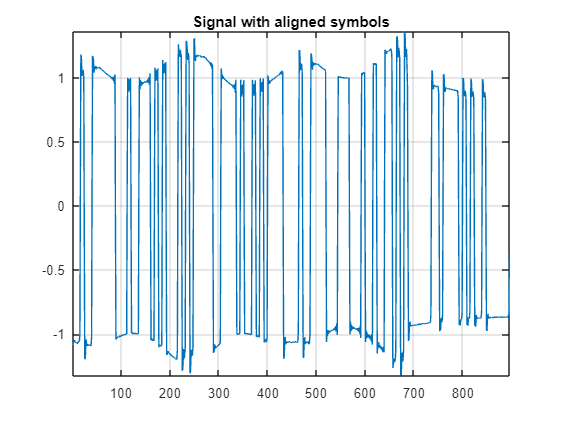

% Initialize energy vector
energy = zeros(samplesPerSymbol,1);

% Compute energy of each symbol
for i = 1:samplesPerSymbol
    value = pulse(i:samplesPerSymbol:end);
    energy(i) = sum(abs(value));

end

%This aligns the symbols by finding the offset where energy is maximized, ensuring proper sampling at symbol boundaries.
[val,ind] = max(energy);       % Find max energy
alignedPulse = pulse(ind:end); % Keep aligned symbols

% Plot
figure
plot (real(alignedPulse))
grid on
axis tight
title("Signal with aligned symbols")

#### Convert into bits

Finally, the last step consists of downsampling the oversampled signal using ***intdump()*** to extract one sample per symbol. Then, the BPSK bits are decoded based on whether the value is positive or negative. However, we need to add some **padding, **to ensure that the total number of samples in *alignedPulse* is an integer multiple of *samplesPerSymbol*. This is important because each symbol in BPSK corresponds to *samplesPerSymbol* samples

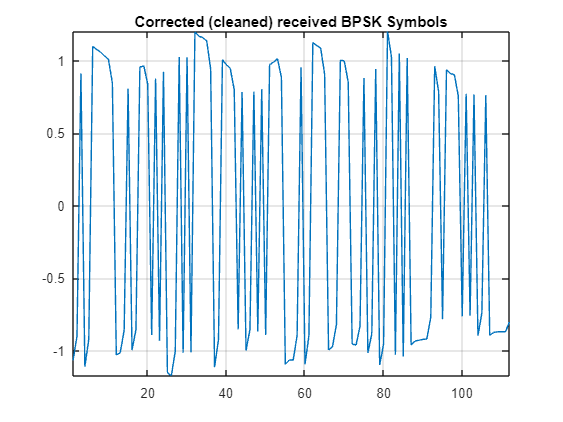

% Compute padding size
%numel(alignedPulse) returns the total number of elements (samples) in the alignedPulse array.
padding = ceil(numel(alignedPulse)/samplesPerSymbol);

% Initialize received data vector, with the proper length
rxData = complex(zeros(padding*samplesPerSymbol,1));

% Received data is the aligned pulse plus padded zeros
rxData(1:numel(alignedPulse)) = alignedPulse;%At the beginning i add the real pulse, alignpulse, and then
%we mantain the zeros

% Decimate received data
rxSymbols_corrected = intdump(rxData,samplesPerSymbol);

figure()
plot(real(rxSymbols_corrected))
grid on
axis tight
title("Corrected (cleaned) received BPSK Symbols")

In the previous graph, we can see the synchronized and received signal downsampled, which means that we have one value per symbol. 

**Constellation of clean symbols**

Once we have applied noise removal and symbol synchronization, the received signal contains **only the cleaned and aligned symbols**. At this stage, we can represent the constellation diagram using the cleaned symbols with:

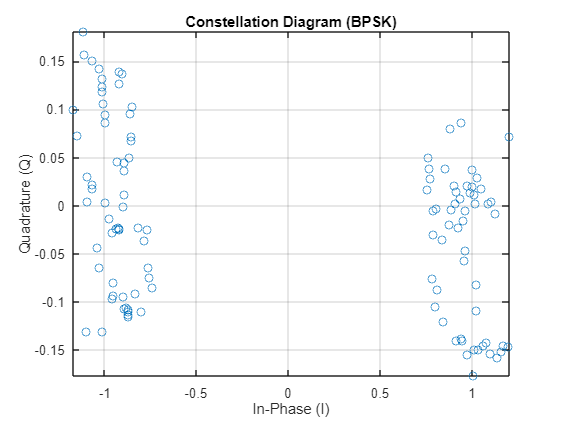

figure()
plot(real(rxSymbols_corrected), imag(rxSymbols_corrected), 'o') 
xlabel('In-Phase (I)')
ylabel('Quadrature (Q)')
title('Constellation Diagram (BPSK)')
grid on
axis tight

In this new constellation diagram:

- The two clusters representing the **BPSK symbols (+1 and -1)** are now clearly visible and properly aligned along the real axis.

- **No samples are present at the center of the constellation**, which were previously observed due to:

                    -    Noise contamination.

                    -    Misaligned or invalid samples from the unprocessed signal.

#### Decoded bits (decision)

At this point, we have processed the received signal to ensure that the symbols are **cleaned** and **synchronized**. The next step is to **decode** the received symbols to recover the original transmitted bits.

We do this using the following steps:

**1. Decoding the Symbols:**To extract the binary bits from the received symbols, we use a simple decision rule based on the sign of each symbol: *rxBits = rxSymbols_corrected <= 0*`;`

This means that:

          - If a received symbol is less than or equal to 0, it corresponds to a **bit value of 1**.

           - If a received symbol is greater than 0, it corresponds to a **bit value of 0**.

**2. Converting the Bits Back to BPSK Symbols:**

We can convert the decoded bits back to their corresponding **BPSK symbols** (+1 or -1).

**3.  Comparing Transmitted and Received Symbols:**

To verify that the receiver has properly decoded the transmitted message, we compare the **received symbols** with the **transmitted symbols**.

- First, we load the transmitted symbols from the previously saved file.

- Then, we downsample the transmitted symbols to match the 1-symbol-per-bit format.

Finally, we can make the representation below for **Visual Comparison, **to ensure that the **transmitted** and **received** symbols are aligned correctly.

 We are creating three plots for comparison:

- The first plot shows the **decoded received BPSK symbols** (*rxSymbols_BPSK*).

- The second plot shows the **transmitted BPSK symbols** (*txSymbols_down*).

- The third plot overlays both the **received** and **transmitted** symbols for a direct visual comparison.

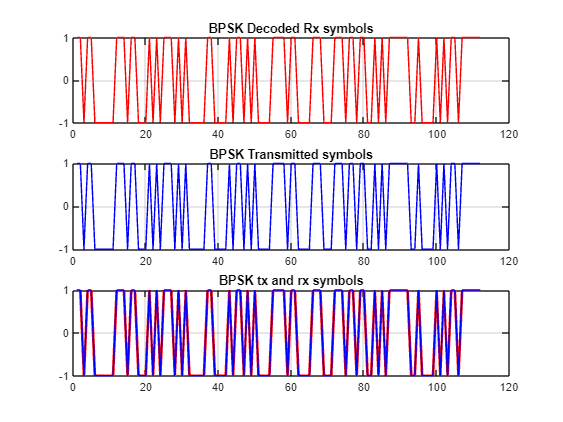

% Compute received bits
rxBits = rxSymbols_corrected <= 0; % <= or >= because BPSK could be inverted

%Convert the received bits to +1/-1 to compare with the transmitted BPSK
%Symbols
rxSymbols_BPSK=sign(rxBits-0.5);

%We can recover the transmitted BPSK Symbols, that have been saved
txSymbols=load('BPSK_IQ_samples_simulation.mat');
txSymbols=txSymbols.IQSamples.Data;

txSymbols_down=txSymbols(897:8:897+(8*112)-1); %1 sample per bit

%They are going to be overlapped so we do 3 graphs

figure()

subplot(3,1,1)
plot(rxSymbols_BPSK,'r')
grid on
title("BPSK Decoded Rx symbols")

subplot(3,1,2)
plot(txSymbols_down,'b')
grid on
title("BPSK Transmitted symbols")

subplot(3,1,3)
plot(rxSymbols_BPSK,'r','LineWidth', 2)
hold on
plot(txSymbols_down,'b')
grid on

title("BPSK tx and rx symbols")

At this stage, we can conclude that we have successfully decoded the final symbols. The comparison plots show:

- **The decoded received symbols (red)**.

- **The transmitted symbols (blue)**.

By overlaying both sets of symbols in the final plot, we can visually confirm that the transmitted and received symbols are **perfectly aligned**. This ensures that the receiver has correctly demodulated and decoded the BPSK message.